# Parameter Estimation for Discrete-SIR models

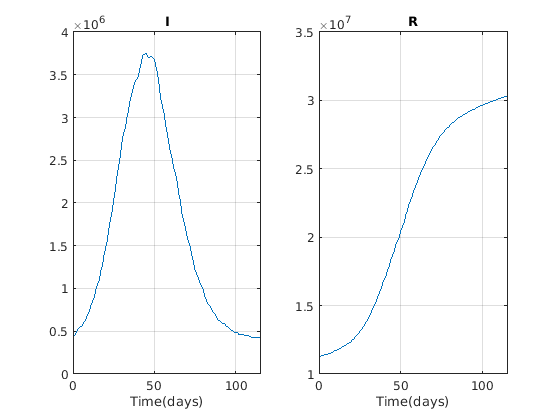

load('Data/India.mat')
ydata = [Cases-Recovered-Death;Recovered; Death];

% ydata = ydata(:, 10:end)';
ydata = [ydata(1,430:end-15); ydata(2,430:end-15); ydata(3,430:end-15)];

VarNames = {'S', 'I', 'R'};
OutNames = {'S', 'I', 'R', 'R_{acc}', 'N'};
ParNames = {'\gamma','\mu','z'};

FullNames = [VarNames,ParNames];

Range1 = [
    143.93e4 143.93e7; 
    ydata(1,1) ydata(1,1);
    0 ydata(2,1)
    ];

Range2 = [
        0 4;        % gamma   
        0 0.01;        % mu
        0 30;        % z
        ];

RangeT = [Range1; Range2];

D = length(ydata(1,:));
Domain = [0 D-1];
xdata = 0:D-1;

for i = 1:2
    subplot(1,2,i)
    plot(ydata(i,:))
    grid on
    title(VarNames(i + 1))
    xlabel("Time(days)")
end

## Parameter estimation model simple, complex and classic probabilities

ModelNames = ["Simple", "Complex", "Classic"];

T_save = cell(2,1);     
N = 10;
extra = struct();
Parameters = [];
Res = [];
 
for i = 1:3
    
    extra.Prob = i;
    %%Prob = 1 -> psi(simple)
    %%Pbro = 2 -> phi(complex)
    
    [T,~] = gsua_dataprep("CHIMERA_SIR", RangeT, 'domain', Domain, 'names',...
        FullNames, 'out_names', OutNames,'opt', extra);
    outs = [2]; 
    T.Properties.CustomProperties.output = outs;
    
    T_save{i} = T;
    
    Solver = 'lsqc';
       
    Opt = optimoptions('lsqcurvefit', 'UseParallel', false,'MaxFunctionEvaluations', 30000, ...
        'MaxIterations', 3000, 'Display','off');
    
%     parfor j = 1:N
    for j = 1:N
        [T_aux, Res_aux] = gsua_pe(T, xdata, ydata(outs,:),...
            'solver', Solver,'N', 1,'opt', Opt,'save', false);
        Parameters(:,j) = T_aux.Estlsqc;
        Res(j) = Res_aux;
    end
    
    [Res, idx] = sort(Res);
    Parameters = Parameters(:,idx);     

    save("Results/Estimations_India_lsqc_out1" + ModelNames(i), "Res",  "Parameters")
    
    figure
    gsua_eval(Parameters(:,1), T, xdata, ydata);
    suptitle(ModelNames(i) + " residual: " + Res(1))
end

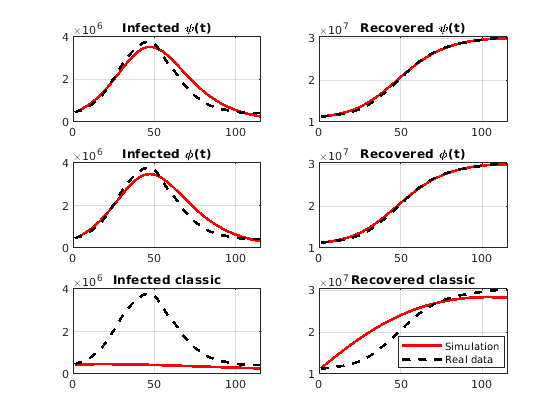

Files = ["Results/Estimations_India_lsqc_Simple.mat","Results/Estimations_India_lsqc_Complex.mat",...
        "Results/Estimations_India_lsqc_Classic.mat"];
Titles = ["Infected \psi(t)", "Recovered \psi(t)", "Infected \phi(t)", "Recovered \phi(t)",...
          "Infected classic", "Recovered classic"];

counter = 1;
figure

for k = 1:3
    load(Files(k))
    N = size(Res, 2);
    ysim = zeros(N, 2, D);
    for i = 1:N
        ysim(i,:,:) = gsua_deval(Parameters(:,i)', T_save{k}, xdata);
      Res(i) = immse(squeeze(ysim(i,:,:)), ydata(1:2,:));
%         Res(i) = norm(squeeze(ysim(i,:,:)) - ydata(1:2,:));
    end
    
    [~, Idx] = sort(Res);
    IdxSims(k) = Idx(1);
    
    for j = 1:2        
        subplot(3,2,counter)
        plot(squeeze(ysim(IdxSims(k), j, :))', 'r','LineWidth',2); 
        hold on
        plot(ydata(j,:)','--k','LineWidth',2)
        grid on
        title(Titles(counter))
        counter = counter +1;
    end
end

legend({"Simulation", "Real data"}, 'location','best')

load(Files(1))
disp("S(0): " + Parameters(1,IdxSims(1)) + ", gamma: " + Parameters(2,IdxSims(1)) +...
    ", mu: " + Parameters(3,IdxSims(1)) + ", z: "+ Parameters(4,IdxSims(1)))

S(0): 26423058.3496, gamma: 2.3099, mu: 0.00059141, z: 0.24675


load(Files(2))
disp("S(0): " + Parameters(1,IdxSims(2)) + ", gamma: " + Parameters(2,IdxSims(2)) +...
    ", mu: " + Parameters(3,IdxSims(2)) + ", z: "+ Parameters(4,IdxSims(2)))

S(0): 27688698.7007, gamma: 2.2876, mu: 0.00086514, z: 0.25078


load(Files(3))
disp("S(0): " + Parameters(1,IdxSims(3)) + ", gamma: " + Parameters(2,IdxSims(3)) +...
    ", mu: " + Parameters(3,IdxSims(3)) + ", z: "+ Parameters(4,IdxSims(3)))

S(0): 1439300000, gamma: 0.022021, mu: 0.01, z: 23.1064


## Equilibriums

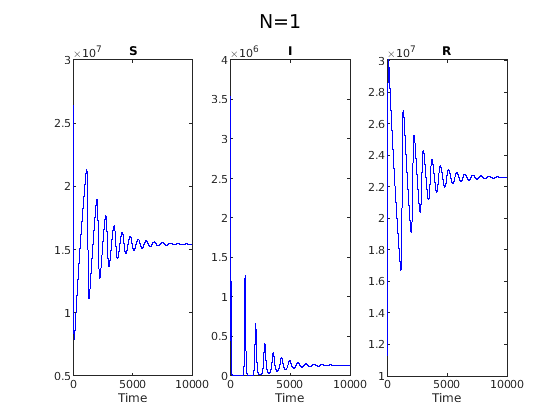

S = 15419426.8879 I = 132747.2713 R = 22618554.1903 N = 38170728.3496


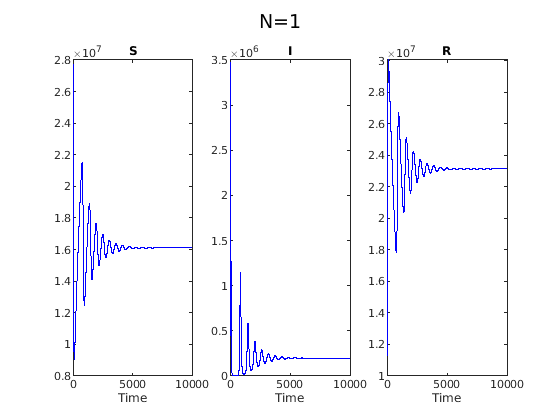

S = 16109041.7552 I = 197311.6002 R = 23130015.3454 N = 39436368.7007


D2 = [10000, 10000];
for i = 1:2
    load(Files(i))    
    T_save{i}.Properties.CustomProperties.Domain(2) = D2(i);
    T_save{i}.Properties.CustomProperties.output = 1:3;
    figure
    y = gsua_eval(Parameters(:,IdxSims(k)), T_save{i}, 0:D2(i));
    disp("S = " + y(1,end,1) + " I = " + y(1,end,2) + " R = " + y(1,end,3) + " N = " + sum(y(:,1,:)))
end

## Identifiability analisys

T_ia = cell(2,1);  
disp(ModelNames(1))

Simple


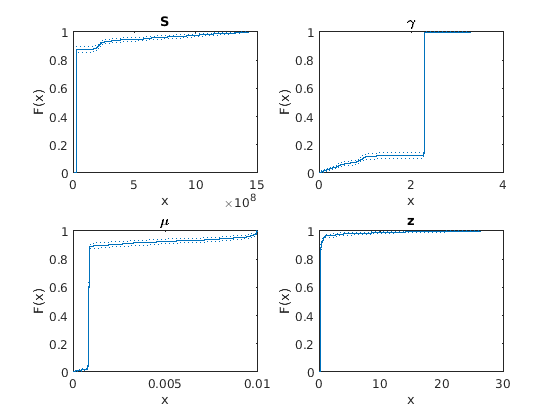

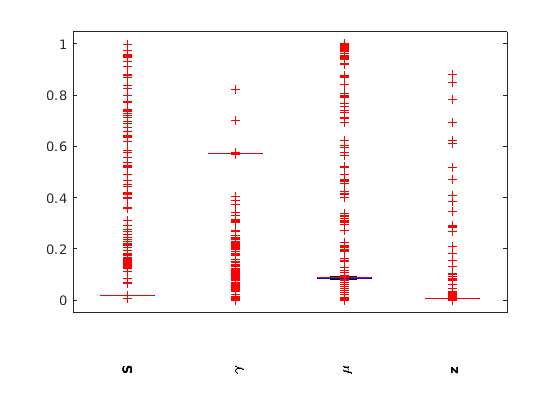

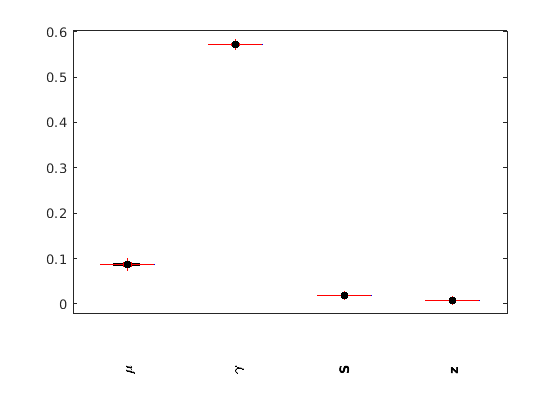

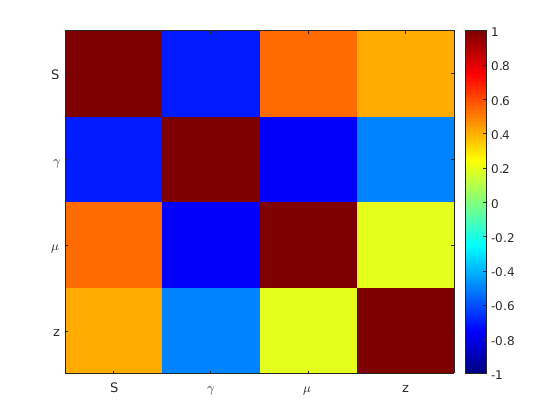

T = 4×4 table
                       Range               Nominal            Est           index 
              ________________________    __________    _______________    _______

    S          1.056e+07    4.4829e+07    2.7694e+07    [1×1000 double]    0.36429
    \gamma        2.2423        2.3323        2.2873    [1×1000 double]    0.38345
    \mu       0.00069882     0.0010336    0.00086619    [1×1000 double]    0.35945
    z           0.087632       0.41396       0.25079    [1×1000 double]    0.19924


T_ia{1} = gsua_ia(T_save{1},Parameters,false,false);

disp(ModelNames(2))

Complex


T = 4×4 table
                       Range               Nominal            Est           index 
              ________________________    __________    _______________    _______

    S          1.056e+07    4.4829e+07    2.7694e+07    [1×1000 double]    0.36429
    \gamma        2.2423        2.3323        2.2873    [1×1000 double]    0.38345
    \mu       0.00069882     0.0010336    0.00086619    [1×1000 double]    0.35945
    z           0.087632       0.41396       0.25079    [1×1000 double]    0.19924


T_ia{2} = gsua_ia(T_save{2},Parameters,false,false);

disp(ModelNames(3))

Classic


T = 4×4 table
                       Range               Nominal            Est           index 
              ________________________    __________    _______________    _______

    S          1.056e+07    4.4829e+07    2.7694e+07    [1×1000 double]    0.36429
    \gamma        2.2423        2.3323        2.2873    [1×1000 double]    0.38345
    \mu       0.00069882     0.0010336    0.00086619    [1×1000 double]    0.35945
    z           0.087632       0.41396       0.25079    [1×1000 double]    0.19924


T_ia{3} = gsua_ia(T_save{3},Parameters,false,false);

**Sensitivity analisys for estimation intervals**

N = 10000;
M = gsua_dmatrix(T, N, 'Method', 'Sobol');

T_save{1} = gsua_sa(M,T_save{1});

Current outputs:1  2  3
Progress: 17%
Estimated processing time (h:m:s): 0:3:33
Remaining time (h:m:s): 0:2:58
Elapsed time (h:m:s): 0:0:35
Estimated stop time (h:m:s): 15:43:27
Number of simulations: 30000
Progress: 34%
Estimated processing time (h:m:s): 0:3:34
Remaining time (h:m:s): 0:2:22
Elapsed time (h:m:s): 0:1:11
Estimated stop time (h:m:s): 15:43:28
Number of simulations: 30000
Finding the deepest curve...


sum(T_save{1}.Si)/sum(abs(T_save{1}.Si))
figure
gsua_plot('Pie',T_save{1},T_save{1}.STi)
figure
gsua_plot('Bar',T_save{1},T_save{1}.STi)
T_save{2} = gsua_sa(M,T_save{2});
sum(T_save{2}.Si)/sum(abs(T_save{2}.Si))
figure
gsua_plot('Pie',T_save{2},T_save{2}.STi)
figure
gsua_plot('Bar',T_save{2},T_save{2}.STi)

Progress: 100%
Estimated processing time (h:m:s): 0:0:0
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 19:1:48
Number of simulations: 1000


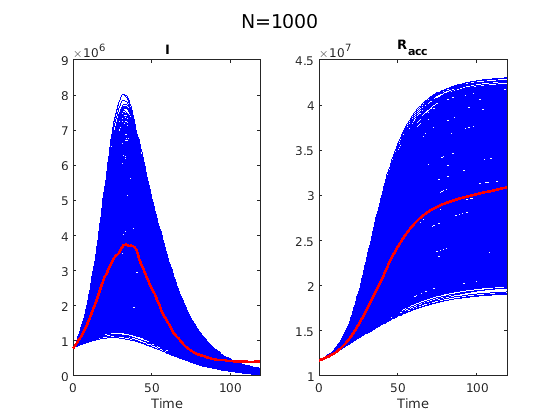

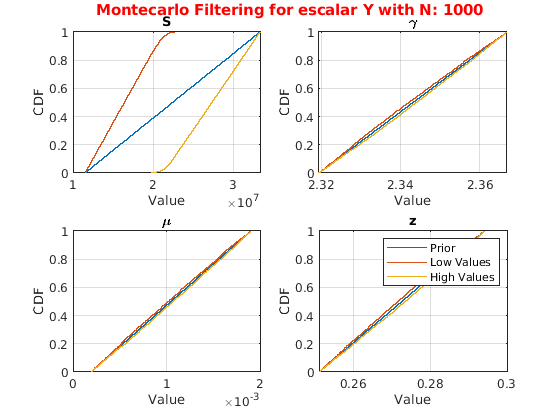

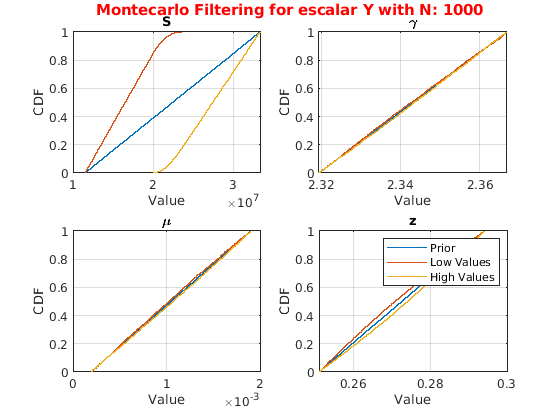

N = 1000;
M = gsua_dmatrix(T_ia{1}, N, 'Method','Sobol');  
gsua_ua(M, T_ia{1},'xdata', xdata, 'ynom', ydata, 'parallel', false);

N = 10000;

M = gsua_dmatrix(T_ia{1}, N, 'Method', 'Sobol');
T_ia{1} = gsua_sa(M,T_ia{1});

Current outputs:1  2  3
Progress: 17%
Estimated processing time (h:m:s): 0:0:52
Remaining time (h:m:s): 0:0:43
Elapsed time (h:m:s): 0:0:8
Estimated stop time (h:m:s): 9:45:15
Number of simulations: 30000
Progress: 34%
Estimated processing time (h:m:s): 0:0:49
Remaining time (h:m:s): 0:0:32
Elapsed time (h:m:s): 0:0:16
Estimated stop time (h:m:s): 9:45:12
Number of simulations: 30000
Finding the deepest curve...
Progress: 50%
Estimated processing time (h:m:s): 0:26:28
Remaining time (h:m:s): 0:13:14
Elapsed time (h:m:s): 0:13:14
Estimated stop time (h:m:s): 10:10:51
Number of simulations: 30000
Progress: 67%
Estimated processing time (h:m:s): 0:20:3
Remaining time (h:m:s): 0:6:41
Elapsed time (h:m:s): 0:13:22
Estimated stop time (h:m:s): 10:4:26
Number of simulations: 30000
Progress: 84%
Estimated processing time (h:m:s): 0:16:12
Remaining time (h:m:s): 0:2:42
Elapsed time (h:m:s): 0:13:30
Estimated stop time (h:m:s): 10:0:35
Number of simulations: 30000
Progress: 100%
Estimated proces

sum(T_ia{1}.Si)/sum(abs(T_ia{1}.Si))

ans = 1

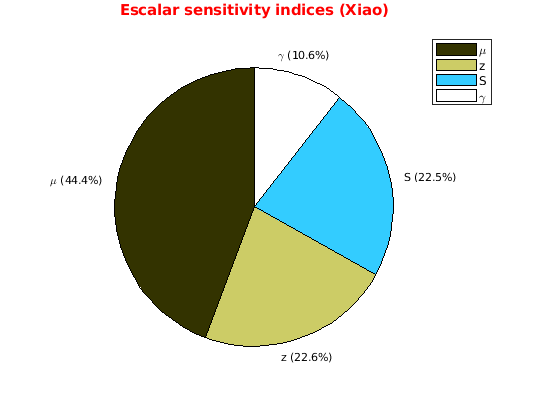

figure
gsua_plot('Pie',T_ia{1},T_ia{1}.STi)

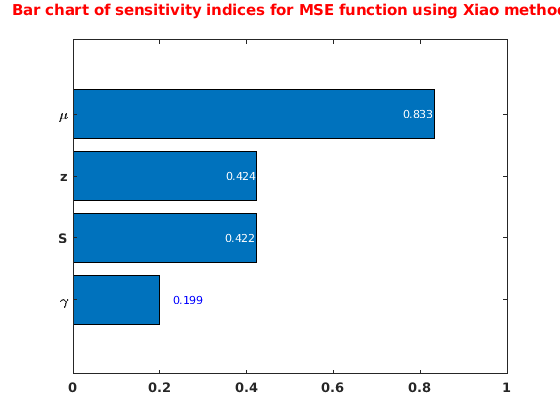

figure
gsua_plot('Bar',T_ia{1},T_ia{1}.STi)

M = gsua_dmatrix(T_ia{2}, N, 'Method', 'Sobol');
T_ia{2} = gsua_sa(M,T_ia{2});

Current outputs:1  2  3
Progress: 17%
Estimated processing time (h:m:s): 0:1:51
Remaining time (h:m:s): 0:1:32
Elapsed time (h:m:s): 0:0:18
Estimated stop time (h:m:s): 9:59:54
Number of simulations: 30000
Progress: 34%
Estimated processing time (h:m:s): 0:1:52
Remaining time (h:m:s): 0:1:15
Elapsed time (h:m:s): 0:0:37
Estimated stop time (h:m:s): 9:59:55
Number of simulations: 30000
Finding the deepest curve...
Progress: 50%
Estimated processing time (h:m:s): 1:31:48
Remaining time (h:m:s): 0:45:54
Elapsed time (h:m:s): 0:45:54
Estimated stop time (h:m:s): 11:29:51
Number of simulations: 30000
Progress: 67%
Estimated processing time (h:m:s): 1:9:25
Remaining time (h:m:s): 0:23:8
Elapsed time (h:m:s): 0:46:17
Estimated stop time (h:m:s): 11:7:28
Number of simulations: 30000
Progress: 84%
Estimated processing time (h:m:s): 0:56:0
Remaining time (h:m:s): 0:9:20
Elapsed time (h:m:s): 0:46:40
Estimated stop time (h:m:s): 10:54:3
Number of simulations: 30000
Progress: 100%
Estimated proces

sum(T_ia{2}.Si)/sum(abs(T_ia{2}.Si))

ans = 1

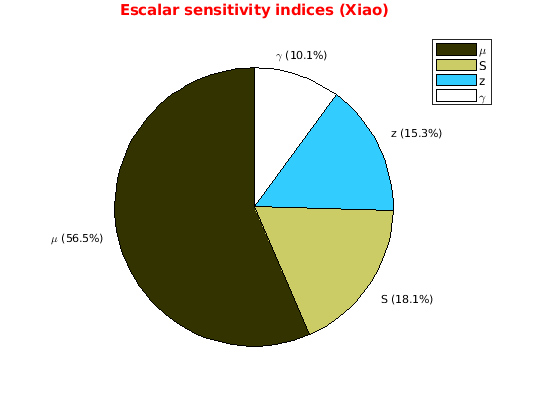

figure
gsua_plot('Pie',T_ia{2},T_ia{2}.STi)

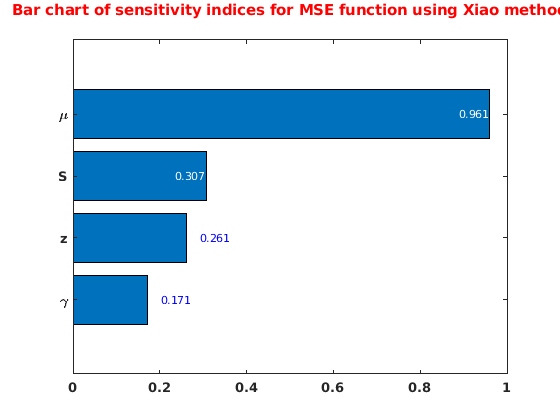

figure
gsua_plot('Bar',T_ia{2},T_ia{2}.STi)

M = gsua_dmatrix(T_ia{3}, N, 'Method', 'Sobol');
T_ia{3} = gsua_sa(M,T_ia{3});

Current outputs:2  3
Progress: 17%
Estimated processing time (h:m:s): 0:0:1
Remaining time (h:m:s): 0:0:1
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 13:25:3
Number of simulations: 30
Progress: 34%
Estimated processing time (h:m:s): 0:0:1
Remaining time (h:m:s): 0:0:1
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 13:25:3
Number of simulations: 30
Finding the deepest curve...
Progress: 50%
Estimated processing time (h:m:s): 0:0:3
Remaining time (h:m:s): 0:0:1
Elapsed time (h:m:s): 0:0:1
Estimated stop time (h:m:s): 13:25:4
Number of simulations: 30
Progress: 67%
Estimated processing time (h:m:s): 0:0:2
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:1
Estimated stop time (h:m:s): 13:25:4
Number of simulations: 30
Progress: 84%
Estimated processing time (h:m:s): 0:0:2
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:1
Estimated stop time (h:m:s): 13:25:4
Number of simulations: 30
Progress: 100%
Estimated processing time (h:m:s): 0:0:1
Remaining time

sum(T_ia{3}.Si)/sum(abs(T_ia{3}.Si))

ans = 0.9990

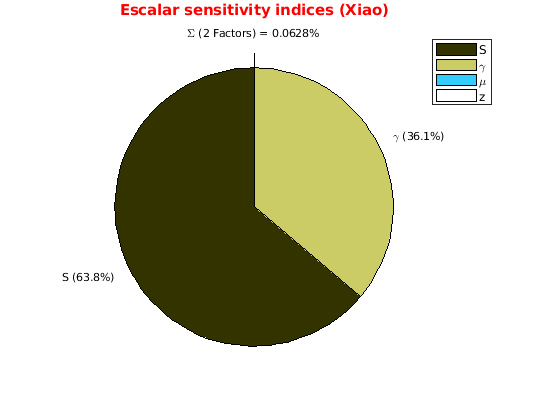

figure
gsua_plot('Pie',T_ia{3},T_ia{3}.STi)

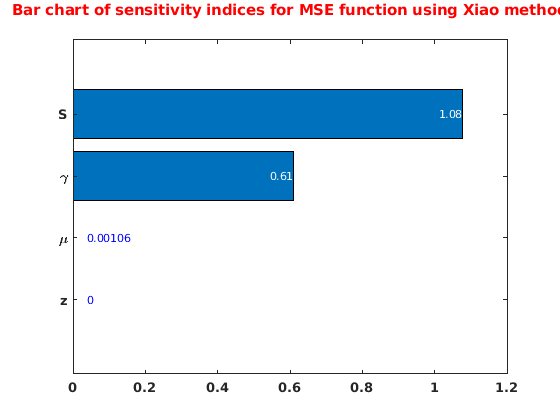

figure
gsua_plot('Bar',T_ia{3},T_ia{3}.STi)

Progress: 100%
Estimated processing time (h:m:s): 0:0:0
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 19:2:2
Number of simulations: 1000


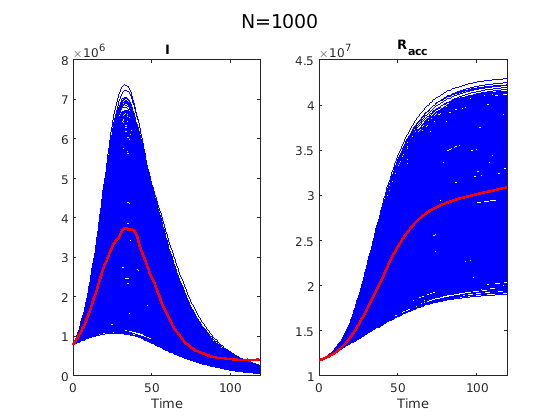

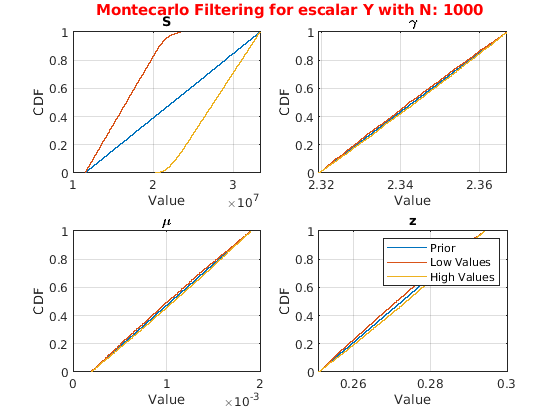

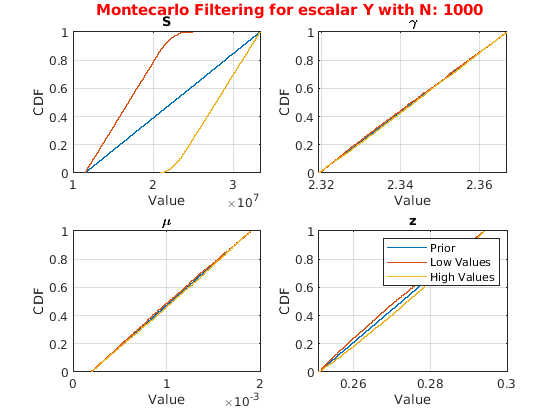

M = gsua_dmatrix(T_ia{2}, N, 'Method','Sobol');  
gsua_ua(M, T_ia{2},'xdata', xdata, 'ynom', ydata, 'parallel', false);